# Testing different models individually and comparing

## Setting up the signal

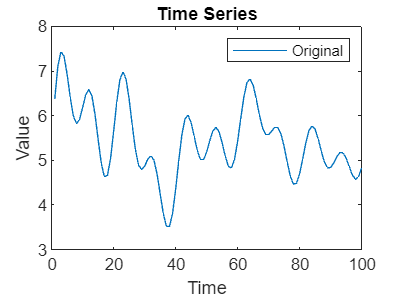

clear all;

addpath('./tensorlab/');

N = 100;
t = (1:N)';

% Determine option testing purposes
signal_option = 3;
noise_option = 1;

% Signal multiplicator
smul = 40*rand();

% Define base signals without decay and random addition
base_signal1 = sin(2 * pi * smul * 0.1 * t);
base_signal2 = sin(2 * pi * smul * 0.05 * t);
base_signal3 = sin(2 * pi * smul * 0.02 * t);

% Apply selected option
switch signal_option
    case 1
        % No decay or random addition
        signal1 = base_signal1;
        signal2 = base_signal2;
        signal3 = base_signal3;
    case 2
        % No random addition
        signal1 = base_signal1 .* exp(-0.01 * t);
        signal2 = base_signal2 .* exp(-0.01 * t);
        signal3 = base_signal3 .* exp(-0.01 * t);
    case 3
        % Everything (decay and random addition)
        signal1 = base_signal1 .* exp(-0.01 * t) + rand() * 10;
        signal2 = base_signal2 .* exp(-0.01 * t) - rand() * 10;
        signal3 = base_signal3 .* exp(-0.01 * t) + rand() * 10;
    case 4
        % No decay, random addition
        signal1 = base_signal1 + rand() * 10;
        signal2 = base_signal2 - rand() * 10;
        signal3 = base_signal3 + rand() * 10;
    otherwise
        error('Invalid option selected');
end

time_series = signal1+signal2+signal3;

% Plot the time series
figure;
plot(time_series);
legend({"Original"})
title('Time Series');
xlabel('Time');
ylabel('Value');

## AR vs SVD

num_experiments = 1;
components = 7;
num_predict = 1;
optimal_order = 20;


predictions_full = zeros(num_predict, num_experiments);
predictions_other = zeros(num_predict, num_experiments);
ground_truths = zeros(num_predict, num_experiments);

for exp=1:num_experiments
    disp("iter "+exp);
    ground_truths(:,exp) = time_series(end-num_predict+1:end);
   
    noisy_series = time_series + noise_option* (0.4*randn(N,1));

    training_series = noisy_series(1:end-num_predict);
    
    % Baseline model
    model2 = ar(training_series, optimal_order);
    predictions_full(:,exp) = forecast(model2, training_series,num_predict);

    % Testing model
    predictions_other(:,exp) = ar_svd(training_series,num_predict,optimal_order,components,'embedding',3);

end

iter 1


disp("done!");

done!



rmse(predictions_full,ground_truths,2)

ans = 5.6843e-14

rmse(predictions_other,ground_truths,2)

ans = 0.0728

## AR vs CPD mean sum

num_experiments = 1;
components = 7;
num_predict = 1;
optimal_order = 10;


predictions_full = zeros(num_predict, num_experiments);
predictions_other = zeros(num_predict, num_experiments);
ground_truths = zeros(num_predict, num_experiments);

for exp=1:num_experiments
    disp("iter "+exp);
    ground_truths(:,exp) = time_series(end-num_predict+1:end);
   
    noisy_series = time_series + noise_option* (0.4*randn(N,1));

    training_series = noisy_series(1:end-num_predict);
    
    % Baseline model
    model2 = ar(training_series, optimal_order);
    predictions_full(:,exp) = forecast(model2, training_series,num_predict);

    % Testing model
    predictions_other(:,exp) = ar_cpd_ms(training_series,num_predict,optimal_order,components,'embedding',3,'even', true, 'L', 7, 'M', 7,'Method', 'mean');

end

iter 1


disp("done!");

done!



rmse(predictions_full,ground_truths,2)

ans = 3.6035e-05

rmse(predictions_other,ground_truths,2)

ans = 124.3971

## AR vs CPD mean full


num_experiments = 1;
components = 7;
num_predict = 1;
optimal_order = 20;


predictions_full = zeros(num_predict, num_experiments);
predictions_other = zeros(num_predict, num_experiments);
ground_truths = zeros(num_predict, num_experiments);

for exp=1:num_experiments
    disp("iter "+exp);
    ground_truths(:,exp) = time_series(end-num_predict+1:end);
   
    noisy_series = time_series + noise_option* (0.4*randn(N,1));

    training_series = noisy_series(1:end-num_predict);
    
    % Baseline model
    model2 = ar(training_series, optimal_order);
    predictions_full(:,exp) = forecast(model2, training_series,num_predict);

    % Testing model
    predictions_other(:,exp) = ar_cpd_mf(training_series,num_predict,optimal_order,components,'embedding',1,'L', 7,'M', 7, 'even', true,'Method', 'mean');

end

iter 1


disp("done!");

done!



rmse(predictions_full,ground_truths,2)

ans = 5.6843e-14

rmse(predictions_other,ground_truths,2)

ans = 0.0223

## AR vs CPD columns sum

num_experiments = 1;
components = 3;
num_predict = 1;
optimal_order = 20;


predictions_full = zeros(num_predict, num_experiments);
predictions_other = zeros(num_predict, num_experiments);
ground_truths = zeros(num_predict, num_experiments);

for exp=1:num_experiments
    disp("iter "+exp);
    ground_truths(:,exp) = time_series(end-num_predict+1:end);


    noisy_series = time_series + noise_option* (0.4*randn(N,1));
    %ground_truths(:,exp) = noisy_series(end-num_predict+1:end);


    training_series = noisy_series(1:end-num_predict);
    
    % Baseline model
    model2 = ar(training_series, optimal_order);
    predictions_full(:,exp) = forecast(model2, training_series,num_predict);

    % Testing model
    predictions_other(:,exp) = ar_cpd_cols(training_series,num_predict,1,components,'embedding',1,'L', 7,'M', 7, 'even', true);

end

iter 1


disp("done!");

done!



rmse(predictions_full,ground_truths,2)

ans = 5.6843e-14

rmse(predictions_other,ground_truths,2)

ans = 0.1470

## AR vs CPD columns full

iter 1


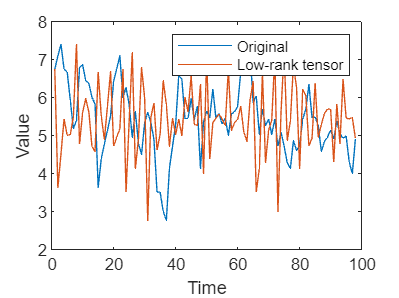

num_experiments = 1;
components = 10;
num_predict = 1;
optimal_order = 20;


predictions_full = zeros(num_predict, num_experiments);
predictions_other = zeros(num_predict, num_experiments);
ground_truths = zeros(num_predict, num_experiments);

for exp=1:num_experiments
    disp("iter "+exp);
    ground_truths(:,exp) = time_series(end-num_predict+1:end);


    noisy_series = time_series + noise_option* (0.4*randn(N,1));
    %ground_truths(:,exp) = noisy_series(end-num_predict+1:end);


    training_series = noisy_series(1:end-num_predict);
    
    % Baseline model
    model2 = ar(training_series, optimal_order);
    predictions_full(:,exp) = forecast(model2, training_series,num_predict);

    % Testing model
    predictions_other(:,exp) = ar_cpd_colf(training_series,num_predict,1,components,'embedding',3,'L', 7,'M', 7, 'even', true,'plotCompare',true);

end

disp("done!");

done!



rmse(predictions_full,ground_truths,2)

ans = 0.0102

rmse(predictions_other,ground_truths,2)

ans = 2.3380

## AR vs MLSVD

iter 1


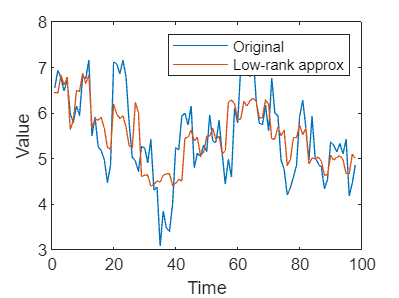

num_experiments = 1;
reduction = 0.1;
num_predict = 1;
optimal_order = 20;


predictions_full = zeros(num_predict, num_experiments);
predictions_other = zeros(num_predict, num_experiments);
ground_truths = zeros(num_predict, num_experiments);

for exp=1:num_experiments
    disp("iter "+exp);
    ground_truths(:,exp) = time_series(end-num_predict+1:end);


    noisy_series = time_series + noise_option* (0.4*randn(N,1));
    %ground_truths(:,exp) = noisy_series(end-num_predict+1:end);


    training_series = noisy_series(1:end-num_predict);
    
    % Baseline model
    model2 = ar(training_series, optimal_order);
    predictions_full(:,exp) = forecast(model2, training_series,num_predict);

    % Testing model
    predictions_other(:,exp) = ar_mlsvd(training_series,num_predict,10,reduction,'embedding',3,'M', 2, 'L', 7, 'even', true, 'plotCompare', true);

end

disp("done!");

done!



rmse(predictions_full,ground_truths,2)

ans = 0.1364

rmse(predictions_other,ground_truths,2)

ans = 0.0518

## AR vs SVD (segmentation)

num_experiments = 1;
components = 7;
num_predict = 1;
optimal_order = 20;


predictions_full = zeros(num_predict, num_experiments);
predictions_other = zeros(num_predict, num_experiments);
ground_truths = zeros(num_predict, num_experiments);

for exp=1:num_experiments
    disp("iter "+exp);
    ground_truths(:,exp) = time_series(end-num_predict+1:end);
   
    noisy_series = time_series + noise_option* (0.4*randn(N,1));

    training_series = noisy_series(1:end-num_predict);
    
    % Baseline model
    model2 = ar(training_series, optimal_order);
    predictions_full(:,exp) = forecast(model2, training_series,num_predict);

    % Testing model
    predictions_other(:,exp) = ar_svd(training_series,num_predict,optimal_order,components,'embedding', 1,'Method',@median);

end

iter 1


disp("done!");

done!



rmse(predictions_full,ground_truths,2)

ans = 8.8818e-15

rmse(predictions_other,ground_truths,2)

ans = 0.0021

data = (1:100)';

h = hankelize(data,'Sizes', [3 2]);

%{
method = 'asdf';
dehankelize(h,'Dims', 1:3,'Method',method);
%}

s = segmentize(data,2,'Segsize',10,'UseAllSamples',true)

s =      1    11    21    31    41    51    61    71    81    91
     2    12    22    32    42    52    62    72    82    92
     3    13    23    33    43    53    63    73    83    93
     4    14    24    34    44    54    64    74    84    94
     5    15    25    35    45    55    65    75    85    95
     6    16    26    36    46    56    66    76    86    96
     7    17    27    37    47    57    67    77    87    97
     8    18    28    38    48    58    68    78    88    98
     9    19    29    39    49    59    69    79    89    99
    10    20    30    40    50    60    70    80    90   100


desegmentize(s)

ans =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10



d = decimate(data, 'Nsamples',[3 2], 'UseAllSamples', false);